P3

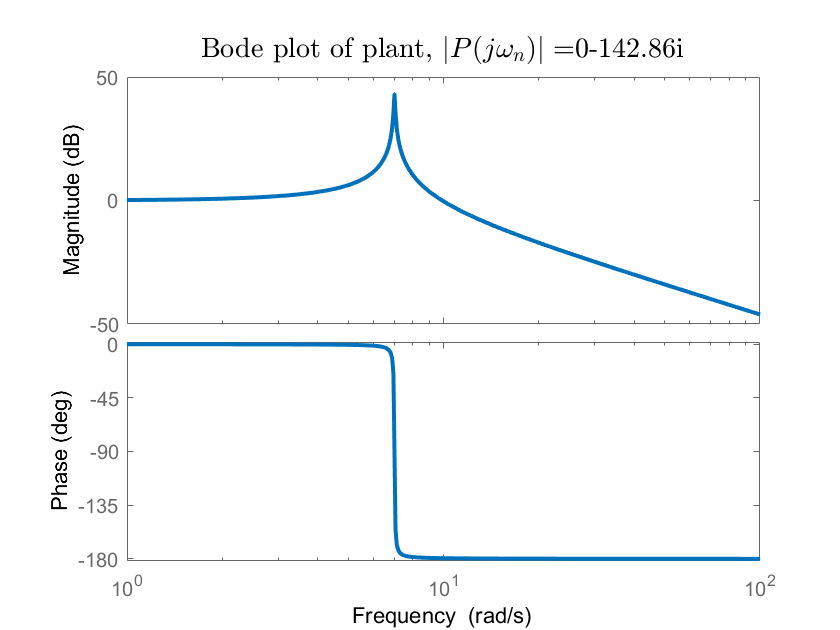

wn = 7;
sigma = 0.0035;
P = tf([wn^2],[1,2*sigma*wn, wn^2]);
[A,B,C,D] = ssdata(P);
% C / (s* eye(2)- A) * B + D
Ppeak = polyval(P.Numerator{1},1j*wn)/polyval(P.Denominator{1},1j*wn);
figure(1)
clf
bode(P)
h = title(['Bode plot of plant, $|P(j\omega_n)| = $',num2str(Ppeak,5)]);
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)

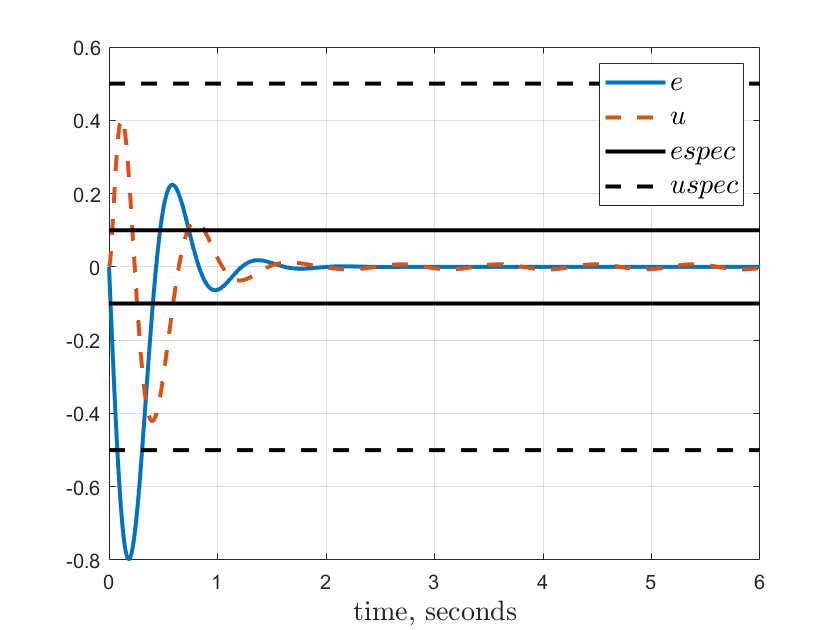


% oscillator model
F =  [0,1; -wn^2,0];

% disturbance and reference output
H =  [1,0];

% augmented oscillator input
G = [0;1];

Aaug =  [A, zeros(2,2);
        G*C, F];

Baug =  [B;0;0];

% cost matrices for LQR 
Q =  diag([100,300,100000,100]);
R =  [1];

% optimal gain for augmented system
Kaug =  lqr(Aaug, Baug, Q,R);

% gain for plant states
K = Kaug(1:2);

% gain for augmented oscillator states
Kw = Kaug(3:4);
Kw1 = Kw(1);
Kw2 = Kw(2);

% state space model to perform simulations using the 
% initial command
Abig = [A, zeros([2,2]), B*H,zeros([2,2]);
        G*C, F, zeros([2,2]), -G*H;
        zeros([2,4]), F, zeros([2,2]);
        zeros([2,6]),F];
Bbig = [B;zeros(6,1)];
Kbig = [K, Kw, zeros(1,4)];


% to simulate error signal
Ce =  [C,0,0,0,0,-H];
De =  0;

% to simulate oscillator states
Cw =  [0,0,1,0,0,0,0,0;
       0,0,0,1,0,0,0,0];
Dw =  [0;0];

% initial condition for disturbance
z0 =  [0;0];
 

% nonzero initial condition for reference
q0 =  [0;wn];


tfinal = 6; % may need to be adjusted
[e,x,t1] = initial(Abig-Bbig*Kbig,Bbig,Ce, De,[0;0;0;0;z0;q0],tfinal);
[u,x,t2] = initial(Abig-Bbig*Kbig,Bbig,-Kbig, 0,[0;0;0;0;z0;q0],tfinal);
[w,x,t3] = initial(Abig-Bbig*Kbig,Bbig,Cw, Dw,[0;0;0;0;z0;q0],tfinal);

% to plot design specifications
const1 = 0.1 * ones(length(t1),1);
const2 = .5 * ones(length(t1),1);

figure(2)
clf
plot(t1,e,'-',t2,u,'--',t1,const1,'k',t1,const2,'k--',t1,-const1,'k',t1,-const2,'k--')
h = legend('$e$','$u$','$e spec$','$u spec$');
set(h,'interpreter','latex','fontsize',14); 
grid
h = xlabel('time, seconds');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)

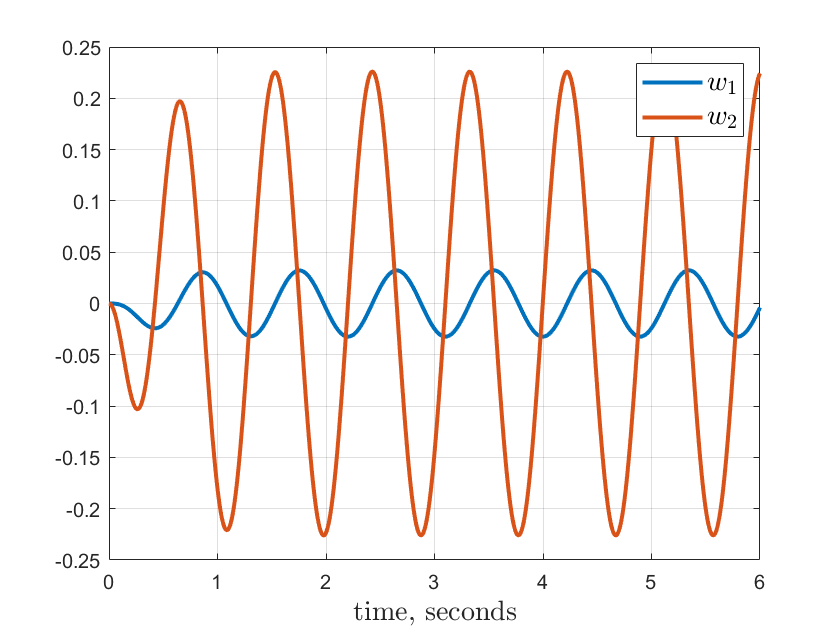


figure(3)
clf
plot(t3,w(:,1),t3,w(:,2))
h = legend('$w_1$','$w_2$');
set(h,'interpreter','latex','fontsize',14); 
grid
h = xlabel('time, seconds');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)

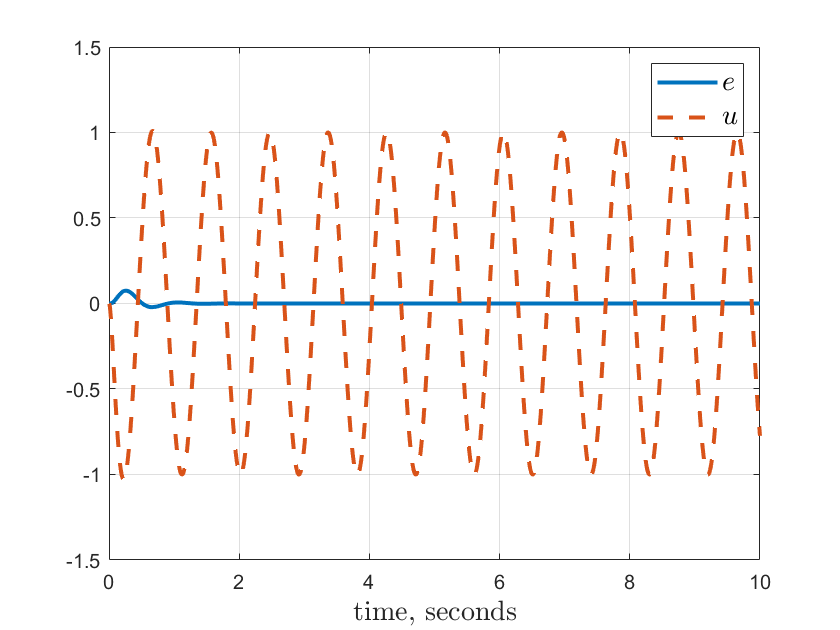


% nonzero initial condition for disturbance
z0 = [0;wn];

% initial condition for reference
q0 = [0;0];

tfinal = 10;% may need to be adjusted
[e,x,t1] = initial(Abig-Bbig*Kbig,Bbig,Ce, De,[0;0;0;0;z0;q0],tfinal);
[u,x,t2] = initial(Abig-Bbig*Kbig,Bbig,-Kbig, 0,[0;0;0;0;z0;q0],tfinal);
[w,x,t3] = initial(Abig-Bbig*Kbig,Bbig,Cw, Dw,[0;0;0;0;z0;q0],tfinal);

figure(4)
clf
plot(t1,e,'-',t2,u,'--');
h = legend('$e$','$u$');
set(h,'interpreter','latex','fontsize',14); 
grid
h = xlabel('time, seconds');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)

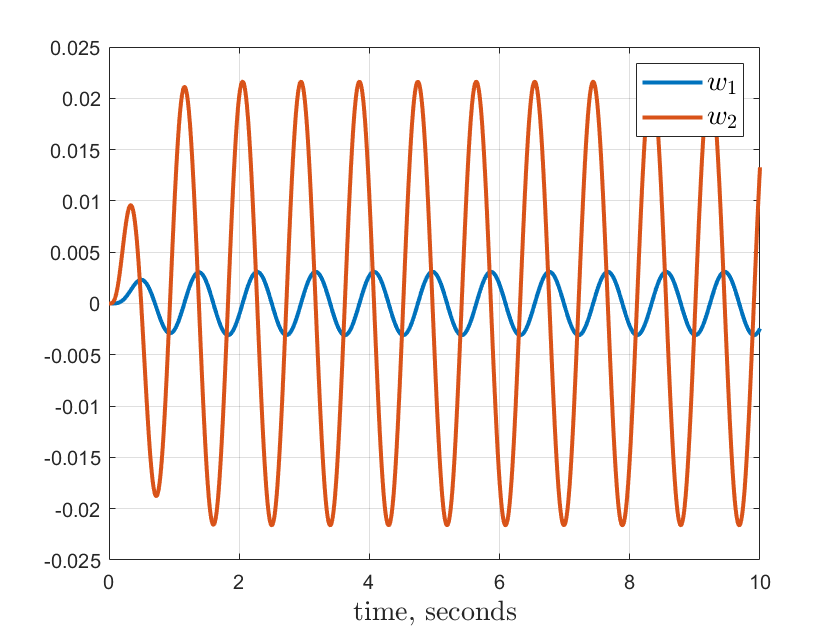


figure(5)
clf
plot(t3,w(:,1),t3,w(:,2))
h = legend('$w_1$','$w_2$');
set(h,'interpreter','latex','fontsize',14); 
grid
h = xlabel('time, seconds');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)

wbar = zeros(length(t3),2);
for i = 1:length(t3)
  wbar(i,:) = expm(-F*t3(i))*w(i,:)';
end  

Aaug2 = [A - B*K, -B*Kw;
        G*C, F];
Baugz = [B*H;zeros(2,2)];
Caugw = [zeros(2,2),-F];
N = -inv(Caugw / Aaug2 * Baugz);

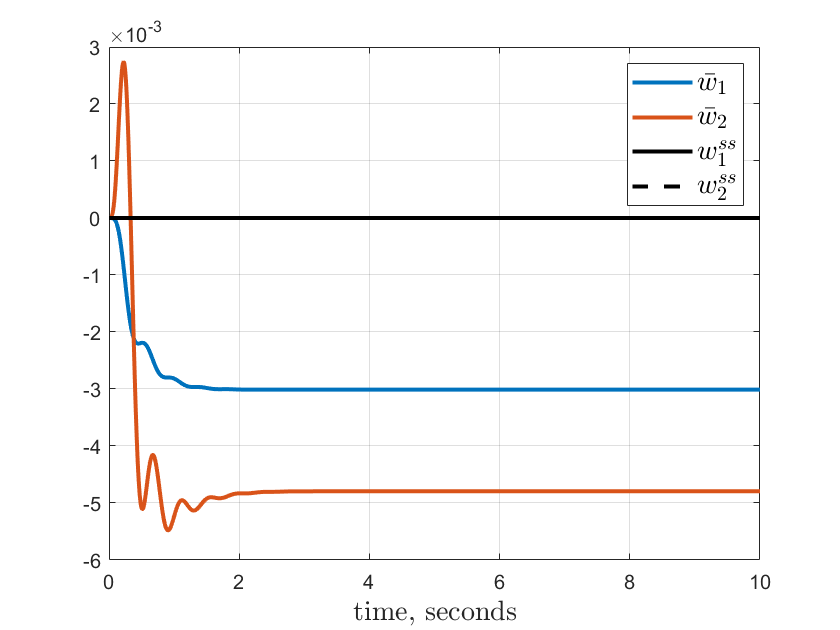


wss = -Caugw / Aaug2 * Baugz * [0;wn];

clear wss1  wss2
for i = 1:length(t3)
    wss1(i,:) = wss(1);
    wss2(i,:) = wss(2);
end    

figure(6)
clf
plot(t3,wbar(:,1),t3,wbar(:,2),t3,wss1,'k-',t3,wss2,'k--')
h = legend('$\bar{w}_1$','$\bar{w}_2$','$w^{ss}_1$','$w^{ss}_2$');
set(h,'interpreter','latex','fontsize',14); 
grid
h = xlabel('time, seconds');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)  

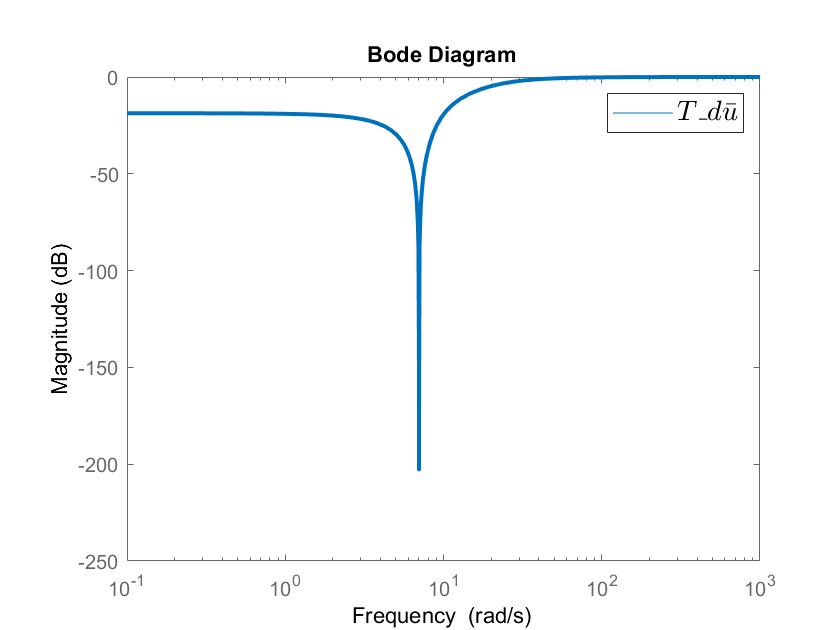


%%% realization of the transfer function from d to ubar

As =  Aaug2;
Bs =  [B;0;0];
Cs =  [-K, -Kw];
Ds =  1;

Tdubar = ss(As,Bs,Cs,Ds);
figure(7)
clf
bodemag(Tdubar)
h = legend('$T_{d\bar{u}}$');
set(h,'interpreter','latex','fontsize',14); 
set(findall(gcf,'type','line'),'linewidth',2)


$$\textrm{Verification}\;\textrm{of}\;\textrm{P1}$$


Aaug2 = [A-B*K, - B * Kw;
        G*C, F];
Bd = [B; 0;0];
Br = [0;0;-G];
Caug = [C,0,0];
Dd = 0;
Dr = -1;
s = tf('s');
Tde = minreal(Caug / (s *eye(4) -Aaug2) * Bd + Dd);
Tre = minreal(Caug / (s * eye(4) - Aaug2) * Br + Dr);

Zeros_of_TF_d2e = tzero(Tde) ,Zeros_of_TF_r2e = tzero(Tre)

Zeros_of_TF_d2e =   -0.0000 + 7.0000i
  -0.0000 - 7.0000i


Zeros_of_TF_r2e =    0.0000 + 7.0000i
   0.0000 - 7.0000i
 -17.9745 +13.1180i
 -17.9745 -13.1180i
